## Wczytanie pliku i analiza spektrogramu

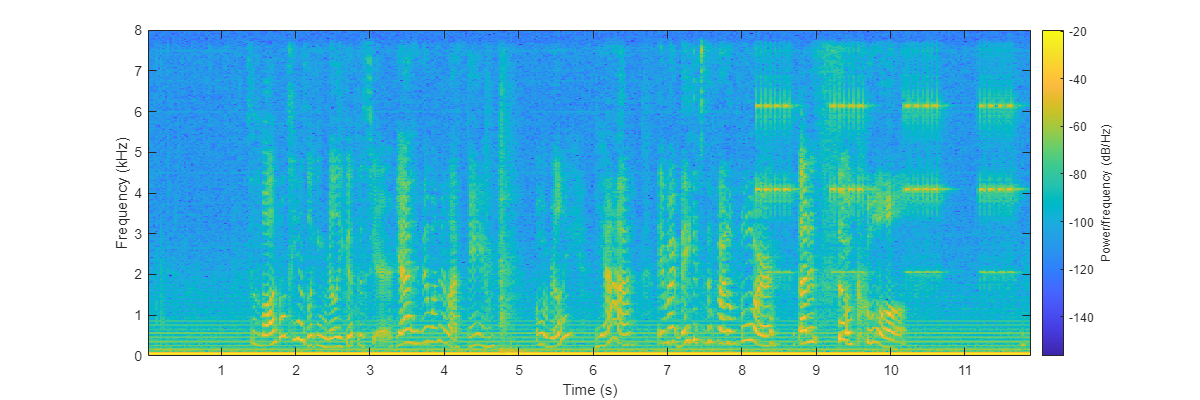

[x, fs] = audioread('noised.wav');

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x, blackman(win_size), win_size/2, [], fs, 'yaxis')

## Przygotowanie i analiza charakterystyki filtrów

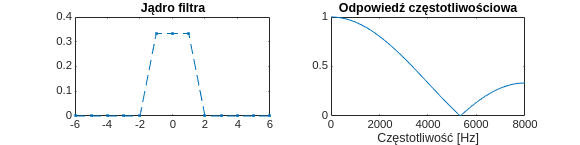

% częstotliwość odcięcia
fc = 500;
% stromość zbocza
fb = 50;

F_low = f_lowpass(fc, fb, fs);
filtstat(F_low, fs);

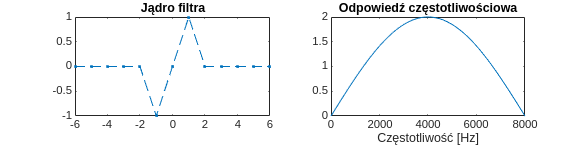

F_high = f_highpass(fc, fb, fs);
filtstat(F_high, fs);

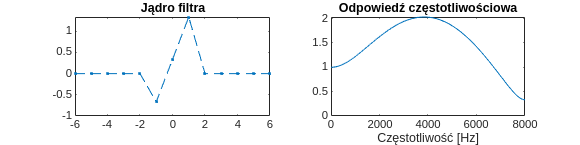

fl = 100;
fh = 300;
F_band = f_bandpass(fl, fh, fb, fs);
filtstat(F_band, fs);

## Filtracja sygnału

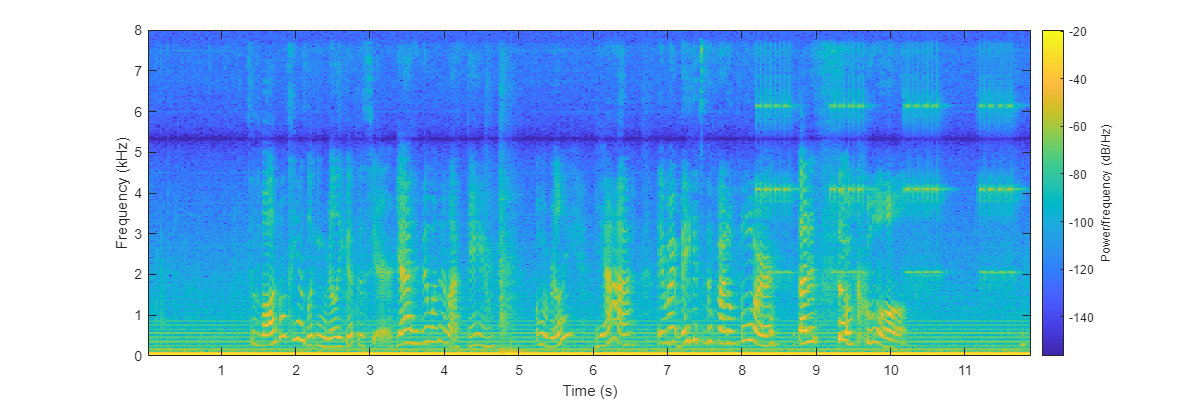

x_filtered = conv(x, F_low, 'same'); % + conv(x, F_high, 'same') + conv(x, F_band, 'same') + ...

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x_filtered, blackman(win_size), win_size/2, [], fs, 'yaxis')

## Odtworzenie przefiltrowanego sygnału

sound(x_filtered, fs);

## Zapis pliku wyjściowego

audiowrite('output.wav', x_filtered, fs);

## Implementacja filtrów

### Argumenty:

- fc - częstotliwość graniczna (Hz)

- fl, fh - częstotliwości graniczne filtra pasmowego (Hz)

- fb - szerokość pasma przejściowego (Hz)

- fs - częstotliwość próbkowania sygnału filtrowanego (Hz)

function F = f_lowpass(fc, fb, fs)
    F = ones(1,3) / 3;
end

function F = f_highpass(fc, fb, fs)
    F = [-1 0 1];
end

function F = f_bandpass(fl, fh, fb, fs)
    F = f_lowpass(fh, fb, fs) + f_highpass(fl, fb, fs);
end

## Funkcje wyświetlające dane

function filtstat(f, fs)
    nfft = 1000;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
        
    y = fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    figure('Position', [10 10 1200 300]);
    subplot(121);
    f_pad = [zeros(1, 5), f, zeros(1, 5)];
    t_pad = (1:length(f_pad)) - round(length(f_pad) / 2);
    plot(t_pad, f_pad, '.--');
    title("Jądro filtra");
    subplot(122);
    plot(f_base, amp);
    title("Odpowiedź częstotliwościowa");
    xlabel("Częstotliwość [Hz]");
end